clear; close all;

Treatment = "ChemoBiM2";
Protocol  = "ThreeFPHoldSRT";
Subject   = "Naveed";

Drives = string(char('A':'Z')');
for i = 1:26
    folder_i = Drives(i)+":\OneDrive";
    if isfolder(folder_i)
        WorkFolder = fullfile(folder_i, "YuLab\GPS_Project\Scripts");
    end
end

DataFolder = fullfile(WorkFolder, "Data", Treatment, Protocol, Subject);

FigFolder  = fullfile(WorkFolder, "Figures", Treatment, Protocol, Subject);
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

DataFile = dir(fullfile(DataFolder, "*Traj*.mat"));
if isempty(DataFile)
    error('No traj data files here');
elseif length(DataFile)>1
    error('More than one traj data file')
end

load(fullfile(DataFolder, DataFile.name));


port_correct = obj.TrialInfo.PortCorrect;
port_chosen  = obj.TrialInfo.PortChosen;
port_plan    = port_correct;

stage     = obj.TrialInfo.Stage;
label     = obj.TrialInfo.Label;
perf      = obj.TrialInfo.Outcome;
fp        = obj.TrialInfo.FP;
hd        = obj.TrialInfo.HD;
rt        = obj.TrialInfo.RT;
mt        = obj.TrialInfo.MT;
mt_median = median(mt(~isoutlier(mt) & perf=="Correct" & stage==1), 'omitnan')

mt_median = 0.4998

mt_median_l = median(mt(~isoutlier(mt) & perf=="Correct" & stage==1 & port_correct==1), 'omitnan')

mt_median_l = 0.5074

mt_median_r = median(mt(~isoutlier(mt) & perf=="Correct" & stage==1 & port_correct==2), 'omitnan')

mt_median_r = 0.4890


speed_dir = obj.trace2mat(obj.SpeedDirHead, obj.TimeFromOut, 0:20:1000*mt_median*0.5);
pos_x     = obj.trace2mat(obj.PosXHead, obj.TimeFromOut, 0:20:1000*mt_median*0.5);
pos_y     = obj.trace2mat(obj.PosYHead, obj.TimeFromOut, 0:20:1000*mt_median*0.5);

pos_x_1   = obj.trace2mat(obj.PosXHead, obj.TimeFromOut, 0:20:200);
pos_y_1   = obj.trace2mat(obj.PosYHead, obj.TimeFromOut, 0:20:200);

left_loc  = mean(cell2mat(obj.PortLeft) - cell2mat(obj.PortCent));
right_loc  = mean(cell2mat(obj.PortRight) - cell2mat(obj.PortCent));


id_l = find(port_chosen==1 & perf=="Correct");
dir_l = speed_dir(id_l, :);
dir_l = rmoutliers(dir_l(dir_l>0));
dir_l_m = mean(dir_l, "all", 'omitnan')

dir_l_m = 105.1105

dir_l_s = std(dir_l, 'omitnan')

dir_l_s = 21.9756


figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
ksdensity(dir_l);
xline(dir_l_m + [-2 2]*dir_l_s, 'LineStyle', ':');

id_r = find(port_chosen==2 & perf=="Correct");
dir_r = speed_dir(id_r, :);
dir_r = rmoutliers(dir_r(dir_r<0));
dir_r_m = mean(dir_r, "all", 'omitnan')

dir_r_m = -96.1714

dir_r_s = std(dir_r, 'omitnan')

dir_r_s = 11.3926

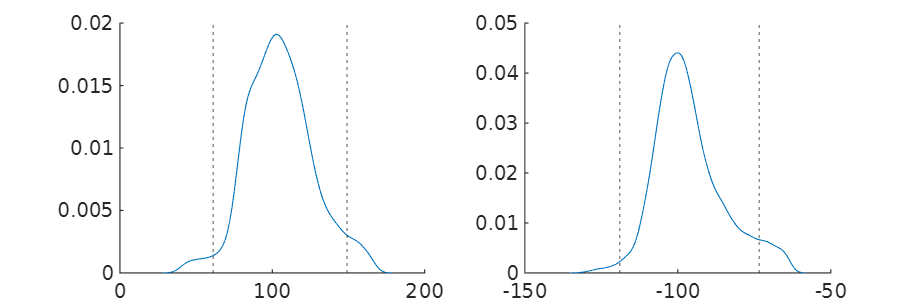


subplot(1, 2, 2); hold on;
ksdensity(dir_r);
xline(dir_r_m + [-2 2]*dir_r_s, 'LineStyle', ':');


change_of_mind = zeros(length(stage), 1);

for i = 1:length(stage)
    if perf=="Wrong"
        switch port_chosen(i)
            case 1
                dir_bias = abs(speed_dir(i, :) - dir_r_m) < 2*dir_l_s;
            case 2
                dir_bias = abs(speed_dir(i, :) - dir_l_m) < 2*dir_r_s;
        end
    else
        switch port_correct(i)
            case 1
                dir_bias = abs(speed_dir(i, :) - dir_r_m) < 2*dir_l_s;
            case 2
                dir_bias = abs(speed_dir(i, :) - dir_l_m) < 2*dir_r_s;
        end
    end
    len_bias = find(diff([0 dir_bias 0])==-1) - find(diff([0 dir_bias 0])==1);
    if any(len_bias >= 5)
        change_of_mind(i) = 1;
        if perf=="Wrong"
            port_plan(i) = 3 - port_chosen(i);
        else
            port_plan(i) = 3 - port_correct(i);
        end
    end
end

for i = 1:length(stage)
    if change_of_mind(i)==1
        continue
    end
    if perf=="Wrong"
        switch port_chosen(i)
            case 1
                dir_bias = abs(speed_dir(i, :) - dir_l_m) < 2*dir_l_s;
            case 2
                dir_bias = abs(speed_dir(i, :) - dir_r_m) < 2*dir_r_s;
        end
    else
        switch port_correct(i)
            case 1
                dir_bias = abs(speed_dir(i, :) - dir_l_m) < 2*dir_l_s;
            case 2
                dir_bias = abs(speed_dir(i, :) - dir_r_m) < 2*dir_r_s;
        end
    end
    len_bias = find(diff([0 dir_bias 0])==-1) - find(diff([0 dir_bias 0])==1);
    if ~any(len_bias >= 5)
        port_plan(i) = 0;
    end
end



perf_this = "Correct";

ratio_noplan_ctrl_left   = sum(port_plan==0 & port_correct==1 & label=="Control" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==1 & label=="Control" & ismember(perf, perf_this) & hd>0.5)

ratio_noplan_ctrl_left = 0.0102

ratio_noplan_chemo_left  = sum(port_plan==0 & port_correct==1 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==1 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5)

ratio_noplan_chemo_left = 0.0119

ratio_noplan_ctrl_right  = sum(port_plan==0 & port_correct==2 & label=="Control" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==2 & label=="Control" & ismember(perf, perf_this) & hd>0.5)

ratio_noplan_ctrl_right = 0.0327

ratio_noplan_chemo_right = sum(port_plan==0 & port_correct==2 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==2 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5)

ratio_noplan_chemo_right = 0.0361

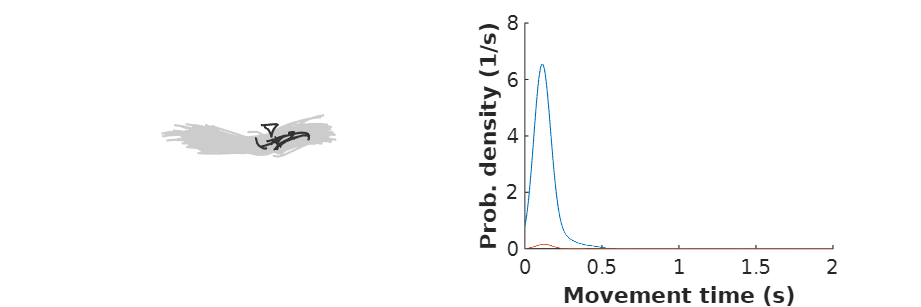


figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
id_no_plan = find(port_plan==0 & ismember(perf, perf_this) & hd>0.5 & label=="Control");
id_planned = find(port_plan~=0 & change_of_mind==0 & ismember(perf, perf_this) & hd>0.5 & label=="Control");
for i = 1:length(id_planned)
    plot(pos_x_1(id_planned(i), :), pos_y_1(id_planned(i), :), 'Color', [.8 .8 .8 .6], 'LineWidth', 1);
end
for i = 1:length(id_no_plan)
    plot(pos_x_1(id_no_plan(i), :), pos_y_1(id_no_plan(i), :), 'Color', [.2 .2 .2 .6], 'LineWidth', 1);
end
set(gca, 'YDir', 'reverse', 'XLim', left_loc(1)*[-1.2 1.2], 'XColor', 'none', 'YColor', 'none'); axis equal

subplot(1, 2, 2); hold on;
if ~isempty(id_planned) && all(ismember(perf_this, ["Correct", "Wrong", "Late"]))
    [f, xi] = ksdensity(rt(id_planned), 0:0.001:2, 'Bandwidth', .05);
    plot(xi, f * (length(id_planned)/length([id_no_plan; id_planned])));
end
if ~isempty(id_no_plan) && all(ismember(perf_this, ["Correct", "Wrong", "Late"]))
    [f, xi] = ksdensity(rt(id_no_plan), 0:0.001:2, 'Bandwidth', .05);
    plot(xi, f * (length(id_no_plan)/length([id_no_plan; id_planned])));
end
xlabel("Movement time (s)", 'FontWeight', 'bold');
ylabel("Prob. density (1/s)", 'FontWeight', 'bold');

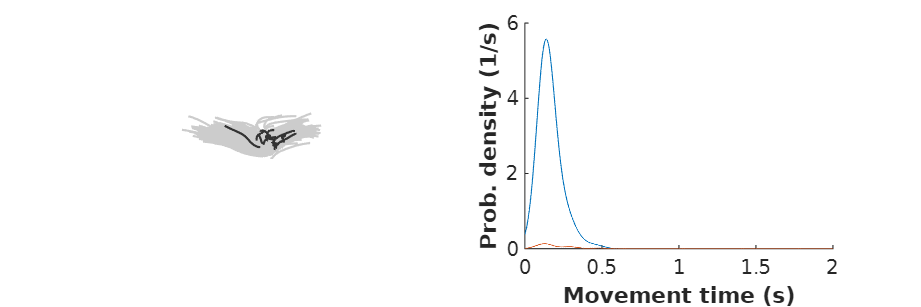


figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
id_no_plan = find(port_plan==0 & ismember(perf, perf_this) & hd>0.5 & label=="Chemo");
id_planned = find(port_plan~=0 & change_of_mind==0 & ismember(perf, perf_this) & hd>0.5 & label=="Chemo");
for i = 1:length(id_planned)
    plot(pos_x_1(id_planned(i), :), pos_y_1(id_planned(i), :), 'Color', [.8 .8 .8 .6], 'LineWidth', 1);
end
for i = 1:length(id_no_plan)
    plot(pos_x_1(id_no_plan(i), :), pos_y_1(id_no_plan(i), :), 'Color', [.2 .2 .2 .6], 'LineWidth', 1);
end
set(gca, 'YDir', 'reverse', 'XLim', left_loc(1)*[-1.2 1.2], 'XColor', 'none', 'YColor', 'none'); axis equal

subplot(1, 2, 2); hold on;
if ~isempty(id_planned) && all(ismember(perf_this, ["Correct", "Wrong", "Late"]))
    [f, xi] = ksdensity(rt(id_planned), 0:0.001:2, 'Bandwidth', .05);
    plot(xi, f * (length(id_planned)/length([id_no_plan; id_planned])));
end
if ~isempty(id_no_plan) && all(ismember(perf_this, ["Correct", "Wrong", "Late"]))
    [f, xi] = ksdensity(rt(id_no_plan), 0:0.001:2, 'Bandwidth', .05);
    plot(xi, f * (length(id_no_plan)/length([id_no_plan; id_planned])));
end
xlabel("Movement time (s)", 'FontWeight', 'bold');
ylabel("Prob. density (1/s)", 'FontWeight', 'bold');

num_plan_ctrl  = sum(port_plan~=0 & label=="Control" & ismember(perf, perf_this) & hd>0.5)

num_plan_ctrl = 586

num_plan_chemo = sum(port_plan~=0 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5)

num_plan_chemo = 516


ratio_plan_ctrl  = sum(port_plan~=0 & label=="Control" & ismember(perf, perf_this) & hd>0.5) / sum(label=="Control" & hd>0.5)

ratio_plan_ctrl = 0.8933

ratio_plan_chemo = sum(port_plan~=0 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5) / sum(label=="Chemo" & hd>0.5)

ratio_plan_chemo = 0.8243

perf_this = "Correct";

ratio_change_ctrl_left   = sum(port_plan==2 & port_correct==1 & label=="Control" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==1 & label=="Control" & ismember(perf, perf_this) & hd>0.5)

ratio_change_ctrl_left = 0.0478

ratio_change_chemo_left  = sum(port_plan==2 & port_correct==1 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==1 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5)

ratio_change_chemo_left = 0.1786

ratio_change_ctrl_right  = sum(port_plan==1 & port_correct==2 & label=="Control" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==2 & label=="Control" & ismember(perf, perf_this) & hd>0.5)

ratio_change_ctrl_right = 0.0033

ratio_change_chemo_right = sum(port_plan==1 & port_correct==2 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5) / sum(port_correct==2 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5)

ratio_change_chemo_right = 0.0072

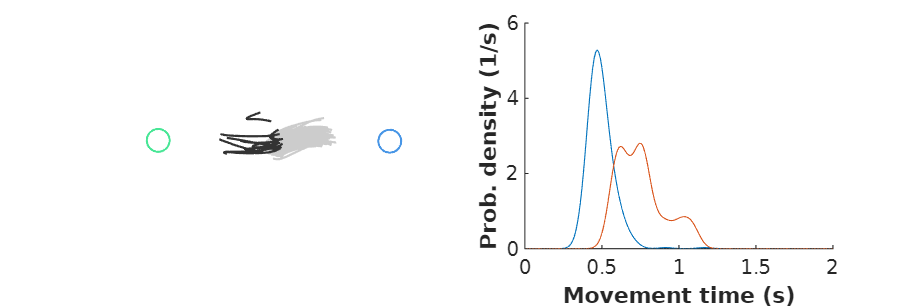


id_change = find(change_of_mind==1 & port_correct==1 & label=="Control" & ismember(perf, perf_this) & hd>0.5);
id_no_change = find(port_plan==1 & port_correct==1 & label=="Control" & ismember(perf, perf_this) & hd>0.5);
figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
viscircles(right_loc, 30, 'Color', GPSColor.PortR, 'LineWidth', 1);
viscircles(left_loc, 30, 'Color', GPSColor.PortL, 'LineWidth', 1);
for i = 1:length(id_no_change)
    plot(pos_x_1(id_no_change(i), :), pos_y_1(id_no_change(i), :), 'Color', [.8 .8 .8 .6], 'LineWidth', 1);
end
for i = 1:length(id_change)
    plot(pos_x_1(id_change(i), :), pos_y_1(id_change(i), :), 'Color', [.2 .2 .2 .6], 'LineWidth', 1);
end
set(gca, 'YDir', 'reverse', 'XLim', left_loc(1)*[-1.2 1.2], 'XColor', 'none', 'YColor', 'none'); axis equal

subplot(1, 2, 2); hold on;
if ~isempty(id_no_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_no_change), 0:0.01:2, 'Bandwidth', .05);
end
if ~isempty(id_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_change), 0:0.01:2, 'Bandwidth', .05);
end
xlabel("Movement time (s)", 'FontWeight', 'bold');
ylabel("Prob. density (1/s)", 'FontWeight', 'bold');

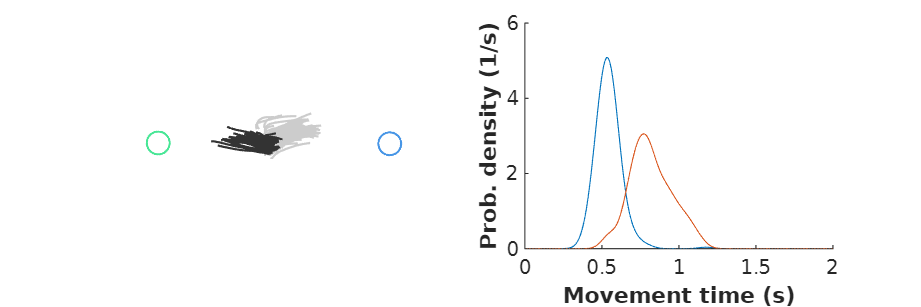


%
id_change = find(change_of_mind==1 & port_correct==1 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5);
id_no_change = find(port_plan==1 & port_correct==1 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5);
figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
viscircles(right_loc, 30, 'Color', GPSColor.PortR, 'LineWidth', 1);
viscircles(left_loc, 30, 'Color', GPSColor.PortL, 'LineWidth', 1);
for i = 1:length(id_no_change)
    plot(pos_x_1(id_no_change(i), :), pos_y_1(id_no_change(i), :), 'Color', [.8 .8 .8 .6], 'LineWidth', 1);
end
for i = 1:length(id_change)
    plot(pos_x_1(id_change(i), :), pos_y_1(id_change(i), :), 'Color', [.2 .2 .2 .6], 'LineWidth', 1);
end
set(gca, 'YDir', 'reverse', 'XLim', left_loc(1)*[-1.2 1.2], 'XColor', 'none', 'YColor', 'none'); axis equal

subplot(1, 2, 2); hold on;
if ~isempty(id_no_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_no_change), 0:0.01:2, 'Bandwidth', .05);
end
if ~isempty(id_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_change), 0:0.01:2, 'Bandwidth', .05);
end
xlabel("Movement time (s)", 'FontWeight', 'bold');
ylabel("Prob. density (1/s)", 'FontWeight', 'bold');

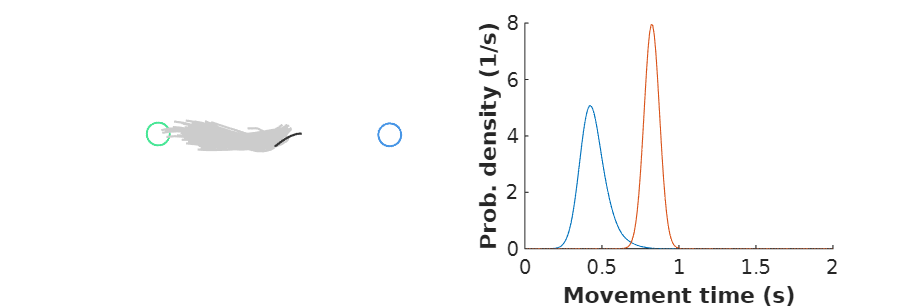


%
id_change = find(change_of_mind==1 & port_correct==2 & label=="Control" & ismember(perf, perf_this) & hd>0.5);
id_no_change = find(port_plan==2 & port_correct==2 & label=="Control" & ismember(perf, perf_this) & hd>0.5);
figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
viscircles(right_loc, 30, 'Color', GPSColor.PortR, 'LineWidth', 1);
viscircles(left_loc, 30, 'Color', GPSColor.PortL, 'LineWidth', 1);
for i = 1:length(id_no_change)
    plot(pos_x_1(id_no_change(i), :), pos_y_1(id_no_change(i), :), 'Color', [.8 .8 .8 .6], 'LineWidth', 1);
end
for i = 1:length(id_change)
    plot(pos_x_1(id_change(i), :), pos_y_1(id_change(i), :), 'Color', [.2 .2 .2 .6], 'LineWidth', 1);
end 
set(gca, 'YDir', 'reverse', 'XLim', left_loc(1)*[-1.2 1.2], 'XColor', 'none', 'YColor', 'none'); axis equal

subplot(1, 2, 2); hold on;
if ~isempty(id_no_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_no_change), 0:0.01:2, 'Bandwidth', .05);
end
if ~isempty(id_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_change), 0:0.01:2, 'Bandwidth', .05);
end
xlabel("Movement time (s)", 'FontWeight', 'bold');
ylabel("Prob. density (1/s)", 'FontWeight', 'bold');

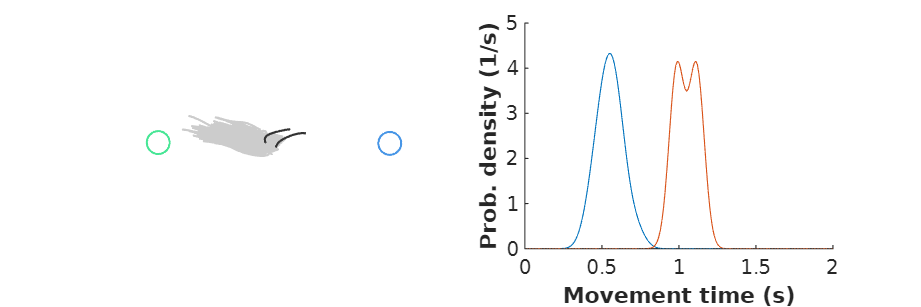


%
id_change = find(change_of_mind==1 & port_correct==2 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5);
id_no_change = find(port_plan==2 & port_correct==2 & label=="Chemo" & ismember(perf, perf_this) & hd>0.5);
figure('Unit', 'Centimeters', 'Position', [5 5 15 5]);
subplot(1, 2, 1); hold on;
viscircles(right_loc, 30, 'Color', GPSColor.PortR, 'LineWidth', 1);
viscircles(left_loc, 30, 'Color', GPSColor.PortL, 'LineWidth', 1);
for i = 1:length(id_no_change)
    plot(pos_x_1(id_no_change(i), :), pos_y_1(id_no_change(i), :), 'Color', [.8 .8 .8 .6], 'LineWidth', 1);
end
for i = 1:length(id_change)
    l = plot(pos_x_1(id_change(i), :), pos_y_1(id_change(i), :), 'Color', [.2 .2 .2 .6], 'LineWidth', 1);
end
set(gca, 'YDir', 'reverse', 'XLim', left_loc(1)*[-1.2 1.2], 'XColor', 'none', 'YColor', 'none'); axis equal

subplot(1, 2, 2); hold on;
if ~isempty(id_no_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_no_change), 0:0.01:2, 'Bandwidth', .05);
end
if ~isempty(id_change) && all(ismember(perf_this, ["Correct", "Wrong"]))
    ksdensity(mt(id_change), 0:0.01:2, 'Bandwidth', .05);
end
xlabel("Movement time (s)", 'FontWeight', 'bold');
ylabel("Prob. density (1/s)", 'FontWeight', 'bold');

id = perf=="Correct" & fp>=1;

a = cellfun(@(x, t) x(find(t<1000, 40, 'last')), obj.AngleHead, obj.TimeFromIn, 'UniformOutput', false);
b = cellfun(@(x, t) x(find(t<1000, 40, 'last')), obj.PosXHead, obj.TimeFromIn, 'UniformOutput', false);
c = cellfun(@(x, t) x(find(t<1000, 40, 'last')), obj.PosYHead, obj.TimeFromIn, 'UniformOutput', false);

a = cell2mat(a(id));
b = cell2mat(b(id));
c = cell2mat(c(id));

a = zscore(a, 0, 'all');
b = zscore(b, 0, 'all');
c = zscore(c, 0, 'all');
x = cat(3, a, b, c);

y = port_plan(id);
lb = label(id);

x_l = x(y==1 & lb=="Control", :, :);
x_r = x(y==2 & lb=="Control", :, :);

coding_dir = median(x_l, 1) - median(x_r, 1);
coding_dir = squeeze(coding_dir);
coding_dir = mean(coding_dir)

coding_dir =    -0.3551   -0.4300    0.4742



proj = zeros(length(x), 40);

for i = 1:length(proj)
    for j = 1:40
        proj(i, j) = dot(squeeze(x(i,j,:)), coding_dir') / norm(coding_dir');
    end
end

figure(); hold on;
plot(mean(proj(y==1 & lb=="Control", :)), 'Color', GPSColor.PortL)
plot(mean(proj(y==2 & lb=="Control", :)), 'Color', GPSColor.PortR)
std(proj(y==1 & lb=="Control", :))

ans =     1.1414    1.1849    1.2293    1.2673    1.3019    1.3344    1.3591    1.3746    1.3817    1.3779    1.3584    1.3216    1.2722    1.2198    1.1723    1.1371    1.1192    1.1164    1.1231    1.1389    1.1630    1.1895    1.2110    1.2259    1.2370    1.2423    1.2434    1.2460    1.2504    1.2531    1.2532    1.2511    1.2443    1.2303    1.2091    1.1830    1.1593    1.1470    1.1487    1.1624


std(proj(y==2 & lb=="Control", :))

ans =     1.1830    1.2262    1.2735    1.3189    1.3670    1.4154    1.4545    1.4819    1.4946    1.4897    1.4704    1.4419    1.4073    1.3711    1.3399    1.3180    1.3059    1.3019    1.3004    1.2998    1.3053    1.3175    1.3293    1.3402    1.3553    1.3735    1.3894    1.4037    1.4198    1.4393    1.4601    1.4771    1.4864    1.4916    1.4993    1.5141    1.5305    1.5426    1.5554    1.5728


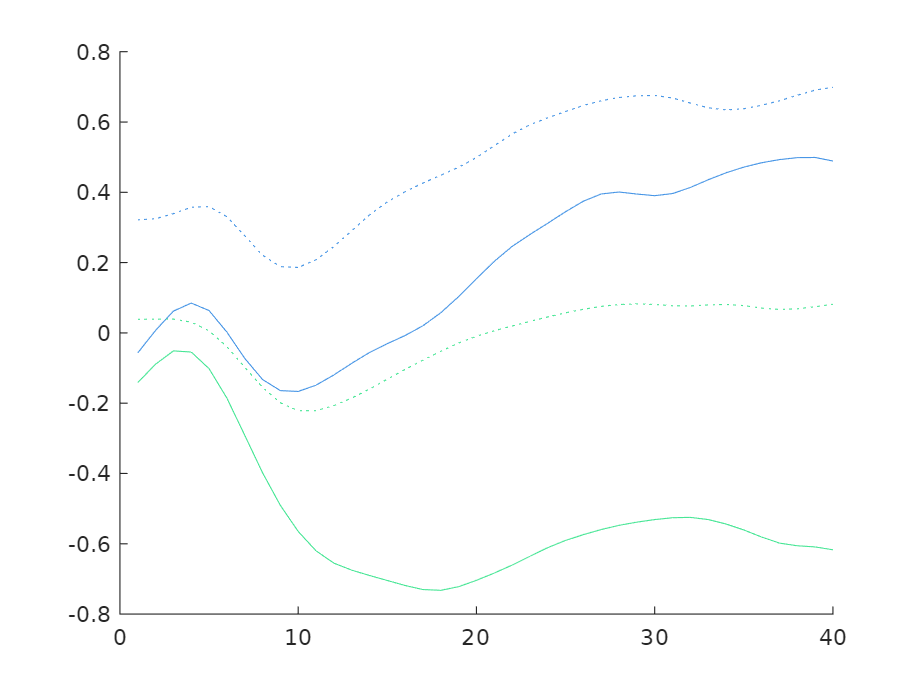


plot(mean(proj(y==1 & lb=="Chemo", :)), 'Color', GPSColor.PortL, 'LineStyle', ':')
plot(mean(proj(y==2 & lb=="Chemo", :)), 'Color', GPSColor.PortR, 'LineStyle', ':')

std(proj(y==1 & lb=="Chemo", :))

ans =     1.1899    1.2381    1.2709    1.2982    1.3341    1.3827    1.4330    1.4675    1.4762    1.4575    1.4193    1.3766    1.3418    1.3193    1.3090    1.3078    1.3123    1.3177    1.3193    1.3135    1.2995    1.2805    1.2628    1.2496    1.2364    1.2152    1.1882    1.1661    1.1562    1.1579    1.1665    1.1761    1.1835    1.1866    1.1791    1.1617    1.1431    1.1248    1.1075    1.0980


std(proj(y==2 & lb=="Chemo", :))

ans =     1.1204    1.1615    1.2064    1.2522    1.2979    1.3403    1.3778    1.4092    1.4309    1.4397    1.4394    1.4333    1.4238    1.4106    1.3880    1.3592    1.3346    1.3181    1.3048    1.2933    1.2895    1.2940    1.3014    1.3068    1.3086    1.3072    1.3053    1.3040    1.3051    1.3066    1.3030    1.2916    1.2749    1.2562    1.2401    1.2313    1.2265    1.2207    1.2110    1.1986


% 
% r = rt(id);
% 
% figure(); hold on
% ksdensity(proj(y==1 & lb=="Control" & ~isoutlier(proj)))
% ksdensity(proj(y==2 & lb=="Control" & ~isoutlier(proj)))
% 
% figure(); hold on;
% scatter(proj(y==1 & lb=="Control" & ~isoutlier(proj)), log10(r(y==1 & lb=="Control" & ~isoutlier(proj))))
% figure(); hold on;
% scatter(proj(y==2 & lb=="Control" & ~isoutlier(proj)), log10(r(y==2 & lb=="Control" & ~isoutlier(proj))))
% 
% figure(); hold on
% ksdensity(proj(y==1 & lb=="Chemo" & ~isoutlier(proj)))
% ksdensity(proj(y==2 & lb=="Chemo" & ~isoutlier(proj)))
% 
% figure(); hold on;
% scatter(proj(y==1 & lb=="Chemo" & ~isoutlier(proj)), log10(r(y==1 & lb=="Chemo" & ~isoutlier(proj))))
% 
% figure(); hold on;
% scatter(proj(y==2 & lb=="Chemo" & ~isoutlier(proj)), log10(r(y==2 & lb=="Chemo" & ~isoutlier(proj))))
% 
% [~, ~, ~, auc_ctrl] = perfcurve(y(lb=="Control"), proj(lb=="Control"), 1)
% [~, ~, ~, auc_chemo] = perfcurve(y(lb=="Chemo"), proj(lb=="Chemo"), 1)

